   files = ["./pca_fixed/fixedata.ply", ...
    "./stl/Busako_printed_scan025_fix.stl", "./pca_fixed/Nov15_pcafix.ply", ...
    "./stl/busako_y+45_.stl", "./stl/busako_y+135_.stl", ...
    "./stl/busako_y-45_.stl", "./stl/busako_x+135_.stl", ...
    "./stl/busako_x+45.stl"];

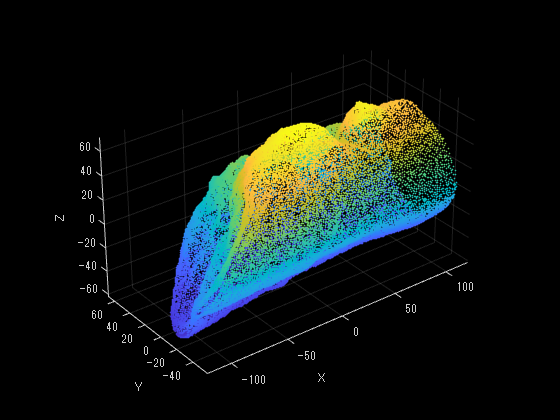

filename = files(7);
if contains(filename, 'stl')
    mesh = stlread(filename);
    scale = 1000;
    pt = (mesh.Points).*scale;
%     pt = mesh.Points;
    sPoint = pointCloud(pt);
elseif contains(filename, 'ply')
    sPoint = pcread(filename);
else
    disp('Not Found');
end
pcshowWithAxes(sPoint);

cutWidthT = 0.5;
axesString = ["x","y","z"];
axes = axesString(1);

originalData= CalculateCircum(sPoint, axes, cutWidthT);

点群が足りないよ


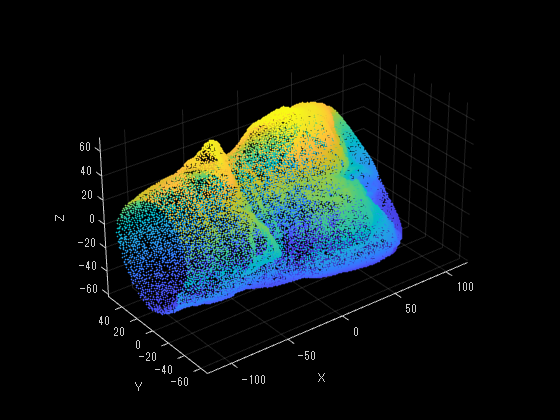

x = originalData(:,1);
area = originalData(:,3);

[~, I] = max(area);
rotAxes = axesString(3);
if x(I) < 0
    sPoint = rotatePoint(sPoint, pi, rotAxes);
    pcshowWithAxes(sPoint);
end

theta = 4* pi/4;
disp(theta);

    3.1416



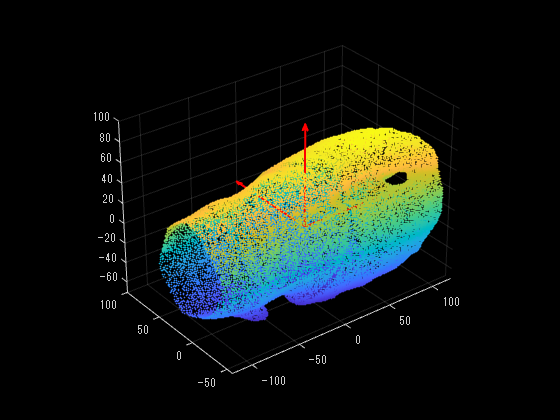

関数または変数 'xLabel' が認識されません。

エラー: ViewAxes (行 10)
    text(xLabel,yLabel,zLabel, num2str((1:numel(xLabel)).'), 'Color','w', 'FontSize',20);

rotate = rotatePoint(sPoint, theta, axes);
pcshow(rotate, 'AxesVisibility','on');
ViewAxes();